## **OFDM explained: Cyclic prefix, equalization, synchronization and oversampling**

## **Darel A. Linebarger**

*Copyright 2021 The MathWorks, Inc.*

Orthogonal Frequency Division Multiplexing (OFDM) is the primary digital modulation technique used by modern wireless communications systems such as 5G cellular and WiFI. The advantages of OFDM over previously used techniques like single carrier QAM are primarily related to the ability to support high speed bit data rates with a simple receiver design. In particular, equalization and synchronization are both simplified by the use of FFT based OFDM with a cyclic prefix (CP).

The code included below first explains basic OFDM, then shows how to augment OFDM with a cyclic prefix. The latter case allows easy use of OFDM in an environment that includes a nonideal channel and unknown propagation delay.

In the last section of the code, we illustrate how OFDM+CP can be modified to efficiently yield an **oversampled** waveform out of the modulator.

For more information, a conceptual explanation of OFDM can be seen at [What Is OFDM? - MATLAB & Simulink](https://www.mathworks.com/discovery/ofdm.html)

MathWorks toolboxes such as [5G Toolbox](https://www.mathworks.com/products/5g.html) include customized OFDM functions that conveniently support data packing and customization of waveforms as prescribed in each of those protocols. 5G OFDM is described at [Generate OFDM modulated waveform - nrOFDMModulate](https://www.mathworks.com/help/5g/ref/nrofdmmodulate.html?searchHighlight=ofdm&s_tid=srchtitle). In addition, basic OFDM [modulation](https://www.mathworks.com/help/comm/ref/ofdmmod.html?searchHighlight=ofdmmod&s_tid=srchtitle) and [demodulation](https://www.mathworks.com/help/comm/ref/ofdmdemod.html) functions are built into the Communications Toolbox.

Now, let's learn a litte bit about OFDM ...

## **Basic OFDM (no cyclic prefix)**

OFDM takes in a buffer of QAM symbols and assigns those across a bank of frequency bins.

Those data are then transformed to overlapping sinuoids by taking an IFFT of the vector of symbols.

% OFDM Transmitter
% - Create a buffer of QAM symbols
m_ary = 16;  % 4 bits per symbol 
Nfft  = 128;
txsymbols = randi([0 m_ary-1], Nfft, 1);
txgrid = qammod(txsymbols, m_ary);

% - Assign QAM symbolx across a bank of frequency bins
txout = ifft(txgrid, Nfft);

% Perfect channel
%  - Transmitter output goes directly to receiver input
rxin = txout;

% OFDM Receiver
% - Reverse Transmit steps by using FFT and QAM Demod
rxgrid = fft(rxin, Nfft);
rxsymbols = qamdemod(rxgrid, m_ary);

% Test output:
assert(isequal(txsymbols, rxsymbols));
disp('OFDM output matches input');

OFDM output matches input


In this example we have filled data into all frequency bins, whereas in practice there are good reasons to not do that. Bins at the edges might be left empty to serve as "guard bands", and some bins may be used to send special "pilot" signals to help with synchronization and equalization.

**Introduce frequency domain equalization and illustrate how to convert circular convolution to linear.**

When a linear channel model is considered, the received signal is the convolution of the transmitted signal with the channel impulse response:

## 
$$y\left(t\right)=h\left(t\right)*u\left(t\right)$$


In the frequency domain, this is:


$$Y\left(f\right)=H\left(f\right)\cdot U\left(f\right)$$


With OFDM, the idea is to use frequency domain equalization to get back to the original transmitted signal:


$$U\left(f\right)=\frac{Y\left(f\right)}{H\left(f\right)}$$


Unfortunately, use of the FFT results in the circular convolution of u with h, whereas we need linear convolution to perform the simple and elegant math shown above. What to do?

**ANSWER**: Use a cyclic prefix

You might consider zero padding the signals in order to make linear convolution and circular give the same result.  That also works, but there are advantages to the CP method over zero padding as you will soon see.

For intro to linear vs circular convolutions and introduction to zero padding in relation, see [Linear and Circular Convolution - MATLAB & Simulink (mathworks.com)](https://www.mathworks.com/help/signal/ug/linear-and-circular-convolution.html)

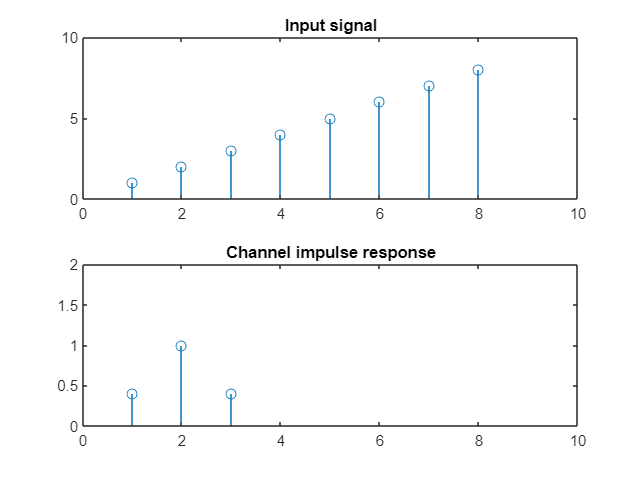

% Test circular convolution, short convolution
u1 = 1:8; % An input signal, must be longer than the channel impulse response (h)
figure
subplot(2,1,1)
stem(u1); axis([0 10 0 10])
title('Input signal')
h = [0.4 1 0.4];    % Represents channel
subplot(2,1,2)
stem(h); axis([0 10 0 2])
title('Channel impulse response')

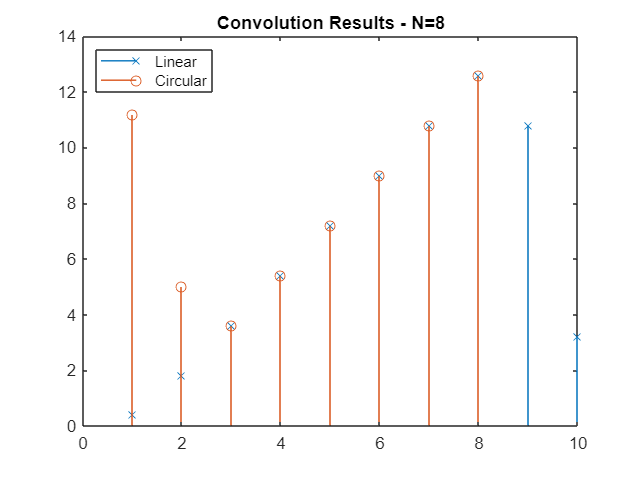


N = length(u1);
yl1 = conv(u1,h);    % Linear convolution, adding smearing effects from channel to output
yc1 = cconv(u1,h,N); % Circular convolution, output is not same as yl1
figure;   stem(yl1,'x')
hold on;  stem(yc1,'o')
title(['Convolution Results - N=',int2str(N)])
legend ('Linear','Circular','Location','northwest')

We see that linear and circular convolution yield different results at some points.

Now let's explore use of a cyclic prefix: repeating the end samples of the symbol so that the linear convolution of a frequency-selective multipath channel can be modeled as circular convolution. In turn, this allows us to use FFT to compute the convolution. Past that, we will also see that this approach also accommodates simple frequency domain processing, such as channel estimation, equalization and synchronization.

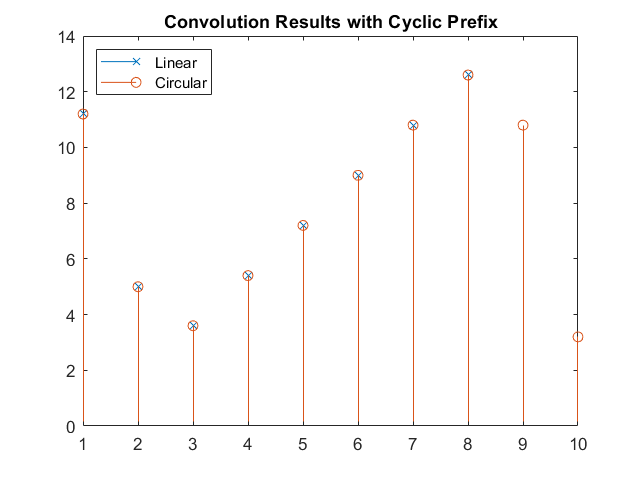

% Use Cyclic Prefix
L = length(h);
N = length(u1);
ucp = u1(N-L+1:N);  % Take last L samples of input u. They will be the cyclic prefix
u2 = [ucp u1];      % Prepend the cyclic prefix to original input to define new input

% Convolution of channel with data+CP
yl2 = conv(u2, h);

% Compare circular convolution to new output yl2.
% First we must remove CP from output:
yl2 = yl2(L+1:end);

figure;  stem(yc1, 'x')
hold on; stem(yl2,'o')
title('Convolution Results with Cyclic Prefix')
legend ('Linear','Circular','Location','northwest')

assert( max(yc1 - yl2(1:N)) < 1e-8);
disp('Linear convolution of sequence with CP matches circular convolution output');

Linear convolution of sequence with CP matches circular convolution output


## **Now, put it all together:**

## **OFDM plus cyclic prefix (CP) and equalization (EQ includes synchronization)**

m_ary = 16;
N = 128;
txsymbols = randi([0 m_ary-1], N, 1);
txgrid = qammod(txsymbols, m_ary);
txout = ifft(txgrid, N);
txout = txout(:);   % Multiple OFDM "symbols" can be processed simultaneously, then serialized
Ncp = 8;            % Must be greater than or equal to length(hchan)
txcp = txout(N-Ncp+1:N);
txout = [txcp; txout];
% In the real world, there is noise. It is ok to add awgn to txout here, but we didn't.

Add impact of the channel

hchan = [0.4 1 0.4].'; % Represents channel
rxin = conv(txout, hchan);      % Add frequency dependent channel impact. Will require EQ.
channelDelay = dsp.Delay(1);    % Could use fractional delay
rxin = channelDelay(rxin);      % Add delay due to channel: latency. Will require sync.

Implement sync and equalization at receiver front end. Set offset=0 to model situation where TX and RX have perfect sync already. Any time offset less than the CP length can be compensated by EQ via additional linear phase.

offset = 1;     % offset=0 means RX and TX are already in sync.
rxsync = rxin(Ncp+1+channelDelay.Length-offset:end); % Throw away CP at receiver - SYNC
rxgrid = fft(rxsync(1:N), N);
useEqualizer = true; % Disable and see that we get wrong answers at receiver output
if useEqualizer
    hfchan = fft(hchan, N);         % Comes from channel estimator in practice
    offsetf = exp(-1i * 2*pi*offset * (0:N-1).'/N); % Linear phase term related to timing offset
    rxgrideq = rxgrid ./ (hfchan .* offsetf); % Estimate of hfchan required in real world.
                                    % Combination of OFDM and CP has made
                                    % equalization easy - just a complex
                                    % scalar for each frequency bin
                                    % Sync is also easy. Just have to get
                                    % within CP prefix, then channel
                                    % estimator does the rest.
else % if you don't equalize, then errors will result
    rxgrideq = rxgrid;
end
rxsymbols = qamdemod(rxgrideq, m_ary);
assert( max(txsymbols - rxsymbols) < 1e-8);
disp('Receiver output matches transmitter input');

Receiver output matches transmitter input


So we see that OFDM+CP facilitates receiver design by making it easier to accomplish equalization and synchronization.

## **One more topic: FFT based oversampling**

So far there has been no discussion of sample rates. Let's talk about that now. In the simplest case, the sample rate is related to subcarrier spacing and FFT length.

SCS = 20e3; % Subcarrier spacing of 20kHz;
fftN = 128;
Fsample = SCS * fftN/2;     % 1.28 MHz
Tsamp = 1 / Fsample;
Tend = Tsamp * (length(txout)-1);
subplot(211)
hold off
plot(0:Tsamp:Tend, real(txout),'*')
title('Real part of transmitter output')
subplot(212)
hold off
plot(0:Tsamp:Tend, imag(txout),'*')
title('Imaginary part of transmitter output')

However, what if we desire the data at a different (presumably higher) sample rate? What are our options? You can certainly apply a sample rate conversion filter to the output of the OFDM modulator.

Now let's modify the previous code to add in the option for overampling on the OFDM modulator output and demodulator input. This can be accomplished efficiently using zero padding with the IFFT in the OFDM modulator. We focus on the simplest case, which is to increase the sample rate by an integer factor.

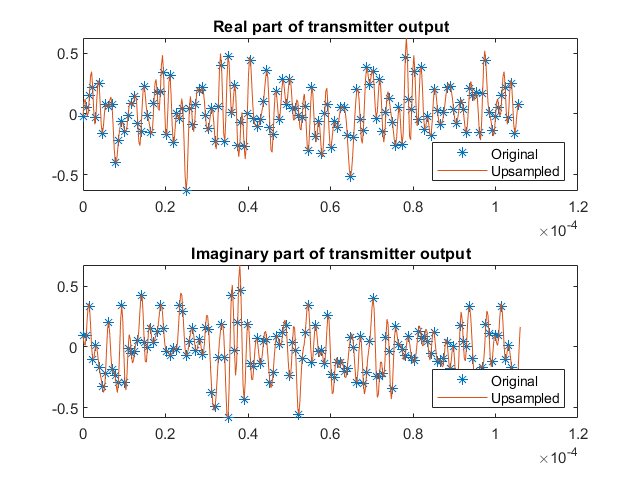

m_ary = 16;
gridN = 128; % Number of elements in grid
upFactor = 3;
fftN  = upFactor * gridN; % FFT length longer than gridN to cause oversampling in time domain
%txsymbols and txgrid: Use same as previous sample for comparison sake
% Zero padding yields higher sample rate. Insert zeros into middle to keep
% correspondence between bin centers for original and upsampled signals
fftgrid = [txgrid(1:gridN/2); zeros((upFactor-1)*gridN,1); txgrid((gridN/2+1):gridN)];
txout = upFactor * ifft(fftgrid, fftN);    % Each column of fftgrid is one OFDM symbol
txout = txout(:);   % Multiple OFDM "symbols" can be processed simultaneously, then serialized
Ncp = 8 * upFactor;            % Must be greater than or equal to length(hchan)
txcp = txout(fftN-Ncp+1:fftN);
txout = [txcp; txout];
% In the real world, there is noise. It is ok to add awgn to txout here, but I didn't.
Tsamp = 1 / (upFactor*Fsample);
Tend = Tsamp * (length(txout)-1);
subplot(211)
hold on
plot(0:Tsamp:Tend, real(txout))
legend ('Original','Upsampled','Location','southeast')
subplot(212)
hold on
plot(0:Tsamp:Tend, imag(txout))
legend ('Original','Upsampled','Location','southeast')

Add impact of the channel

hchan = [0.4 1 0.4].'; % Represents channel. In reality would take upFactor into account.
rxin = conv(txout, hchan);      % Add frequency dependent channel impact. Will require EQ.
channelDelay = dsp.Delay(1);    % Could use fractional delay
rxin = channelDelay(rxin);      % Add delay due to channel: latency. Will require sync.

Implement sync and equalization at receiver front end. Set offset=0 to model situation where TX and RX have perfect sync already. Any offset less than the CP length can be compensated by EQ (additional linear phase term).

offset = 2 * upFactor;      % offset=0 means RX and TX are already in sync.
rxsync = rxin(Ncp+1+channelDelay.Length-offset:end); % Throw away CP at receiver - SYNC
rxgrid = fft(rxsync(1:fftN), fftN) / upFactor;  % Additional upFactor term only required
                                                % for direct comparison of signals at
                                                % different rates.
useEqualizer = true; % Disable and see that we get wrong answers at receiver output
if useEqualizer
    hfchan = fft(hchan, fftN);         % Comes from channel estimator in practice
    offsetf = exp(-1i * 2*pi*offset * (0:fftN-1).'/fftN); % Lin phase term for timing offset
    rxgrideq = rxgrid ./ (hfchan(:) .* offsetf); % Estimate of hfchan required in real world.
                                    % Combination of OFDM and CP has made
                                    % equalization easy - just a complex
                                    % scalar for each frequency bin
                                    % Sync is also easy. Just have to get
                                    % within CP prefix, then channel
                                    % estimator does the rest.
else % if you don't equalize, then errors will result
    rxgrideq = rxgrid;
end
rxgridNoZeroPad = [rxgrideq(1:gridN/2); rxgrideq((1+(upFactor-0.5)*gridN):end)];
rxsymbols = qamdemod(rxgridNoZeroPad, m_ary);
assert( max(txsymbols - rxsymbols) < 1e-8);
disp('Oversampled Receiver output matches transmitter input');

Oversampled Receiver output matches transmitter input


## Use OFDM routines from Communications Toolbox and Compare to Above

% OFDM Transmitter
% - Create a buffer of QAM symbols
m_ary = 16;  % 4 bits per symbol 
Nfft  = 128;
txsymbols = randi([0 m_ary-1], Nfft, 1);
txgrid = qammod(txsymbols, m_ary);

% - Assign QAM symbolx across a bank of frequency bins
txout_ifft = ifft(txgrid, Nfft);
txout_ofdmmod = ofdmmod(txgrid, Nfft, 0);

% Note that the modulated outputs from the IFFT and that from OFDMMOD
% are the same except that every other point has opposite sign. What's up
% with that?
[txout_ifft(1:10) txout_ofdmmod(1:10)]

ans =    0.0312 - 0.1719i   0.0312 - 0.1719i
  -0.1853 - 0.2336i   0.1853 + 0.2336i
   0.0010 + 0.0491i   0.0010 + 0.0491i
  -0.3616 + 0.1696i   0.3616 - 0.1696i
   0.2029 - 0.0772i   0.2029 - 0.0772i
  -0.0987 - 0.3816i   0.0987 + 0.3816i
  -0.0594 - 0.0756i  -0.0594 - 0.0756i
   0.4121 - 0.3507i  -0.4121 + 0.3507i
  -0.1460 - 0.1354i  -0.1460 - 0.1354i
   0.0253 - 0.1567i  -0.0253 + 0.1567i


% The function OFDMMOD assumes that the input grid data has DC (or center
% frequency) at the center of the data (from -Fs/2 to +Fs/2) and executes an FFTSHIFT command
% prior to executing the IFFT. This puts the data in proper order for the
% the IFFT: from 0 to Fs.
% The FFTSHIFT which swaps upper and lower half of the input data can also
% be viewed as a time shift by N/2: x(n) -> x(n-N/2). That time shift
% introduces a linear phase term which resolves to (-1)^n in this case.
% It all works out so long as you are consistent and either include or
% exclude the fftshift from both modulation and demodulation steps.
%
% Perfect channel
%
% OFDM Receiver
% - Reverse Transmit steps by using FFT and QAM Demod
rxgrid_ifft = fft(txout_ifft, Nfft);
rxsymbols_ifft = qamdemod(rxgrid_ifft, m_ary);
rxgrid_ofdmdemod = ofdmdemod(txout_ofdmmod, Nfft, 0);
rxsymbols_ofdmdemod = qamdemod(rxgrid_ofdmdemod, m_ary);
% Test output:
assert(isequal(rxsymbols_ifft, rxsymbols_ofdmdemod));
disp('IFFT based OFDM matches that from ofdmdemod');

IFFT based OFDM matches that from ofdmdemod


That is the end of this introductory tour of OFDM! I hope you found it instructional. In reality, some of the more highly integrated OFDM functions are likely to be more useful for building or modeling systems. This intro was intended for people first learning how to practice and use OFDM so that they develop a good intuitive understanding of how it works.